# STEP 3 — SYNTHETIC SENSOR GENERATION

This file turns the ideal reference motion into a simulated sensing problem. We first define a ground-truth state, including position, velocity, acceleration and attitude. We then generate what a camera and an IMU would measure if that state were observed with realistic noise and fixed sensor bias. The important distinction is that the true quantities are known only because we are creating the simulation; the estimator in Step 4 must work from the generated measurements rather than being given the truth directly.

## 1. Load the trajectory and establish ground truth

The trajectory from Step 2 is treated as the motion that the simulated drone is actually following. Thus pd, vd and ad become p_true, v_true and a_true. Keeping these arrays explicitly labelled as true values prevents us from confusing a simulated measurement with the physical quantity that generated it.


$$\mathcal{X}_{true}(t)=\{\mathbf{p}_{true},\mathbf{v}_{true},\mathbf{a}_{true},R_{true},\mathbf{\omega}_{true}\}$$


The gravity vector is expressed in the inertial frame. With z positive upward, gravity points in the negative z direction.


$$\mathbf{g}=\matrix{0 \cr 0 \cr-9.81}\;\mathrm{m/s^2}$$


The following blocks load the data, create the ground-truth arrays and define gravity.

load('drone_toy_model.mat');
whos

  Name                             Size            Bytes  Class     Attributes

  A                                6x6               288  double              
  Acc                           1001x6             48048  double              
  P                             1001x6             48048  double              
  T                                1x1                 8  double              
  V                             1001x6             48048  double              
  a0                               1x3                24  double              
  a0_axis                          1x1                 8  double              
  acceleration_final_error         1x1                 8  double              
  acceleration_start_error         1x1                 8  double              
  ad                            1001x3             24024  double              
  af                               1x3                24  double              
  af_axis                          1x1             

This block loads the trajectory into the workspace and creates the arrays that will be treated as the true motion. The true position, velocity and acceleration are copied from the desired trajectory so that the sensor model has a known reference against which its errors can later be measured.


$$\mathbf p_{true}=\mathbf p_d,\qquad \mathbf v_{true}=\mathbf v_d,\qquad \mathbf a_{true}=\mathbf a_d$$


clc;
clear;
close all;

%% STEP 3: SYNTHETIC SENSOR GENERATION

% Load trajectory generated in Step 2
load('drone_toy_model.mat');


%% 1. Use Step 2 Trajectory as Ground Truth

% The trajectory generated in Step 2 is treated as
% the true motion of the drone.

numSamples = length(t);

p_true = pd
v_true = vd;

p_true =          0         0         0
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0000
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001


a_true = ad;

Gravity is a known inertial-frame quantity, so it is defined once and then reused by the accelerometer model. With the chosen convention, z is positive upward and gravitational acceleration acts in the negative z direction.


$$\mathbf g=[0\;0\;-9.81]^T\;\mathrm{m/s^2}$$


g = [0; 0; -9.81];

## 2. Construct the true attitude from the motion

The drone needs an orientation R_true(t) because an IMU measures acceleration and angular velocity in the body frame, whereas the trajectory is defined in the inertial frame. For this toy model the yaw is chosen from the horizontal direction of travel.


$$\psi={atan2}(v_y,v_x)$$


If the horizontal speed is almost zero, the direction of travel does not define a useful yaw, so the code uses zero as a fallback. Pitch and roll are approximated from the horizontal acceleration components relative to gravity.


$$\theta=\mathrm{atan2}(a_x,g_0),\qquad \phi=-\mathrm{atan2}(a_y,g_0),\qquad g_0=9.81$$


The variables yaw, pitch and roll are angles in radians. 

%% 3. Generate True Orientation

R_true = zeros(3,3,numSamples);

for k = 1:numSamples

    % -----------------------------------------------------
    % Desired yaw
    % -----------------------------------------------------

    if norm(v_true(k,1:2)) > 1e-4

        yaw = atan2( ...
            v_true(k,2), ...
            v_true(k,1));

    else

        yaw = 0;

    end

The pitch and roll are estimated from the horizontal acceleration relative to gravity. These expressions are only an approximation used to create a convenient toy-model attitude; they are not a full attitude-estimation algorithm.


$$\theta=\mathrm{atan2}(a_x,9.81),\qquad \phi=-\mathrm{atan2}(a_y,9.81)$$



    % -----------------------------------------------------
    % Approximate pitch
    % -----------------------------------------------------

    pitch = atan2( ...
        a_true(k,1), ...
        9.81);


    % -----------------------------------------------------
    % Approximate roll
    % -----------------------------------------------------

    roll = -atan2( ...
        a_true(k,2), ...
        9.81);


## 3. Build the rotation matrix

A rotation about each coordinate axis has a standard matrix representation. The X, Y and Z rotations are combined in the order Z after Y after X. This is the same type of rotation-matrix construction used in the professor notes when the three elemental rotations are combined.


$$R_x(\phi)=\left[\matrix{1 & 0 & 0 \cr 0 & \cos\phi & -\sin\phi \cr 0 & \sin\phi & \cos\phi}\right]$$



$$R_y(\theta)=\left[\matrix{\cos\theta & 0 & \sin\theta \cr 0 & 1 & 0 \cr -\sin\theta & 0 & \cos\theta}\right]$$



$$R_z(\psi)=\left[\matrix{\cos\psi & -\sin\psi & 0 \cr \sin\psi & \cos\psi & 0 \cr 0 & 0 & 1}\right]
$$



$$R_{true}=R_z(\psi)R_y(\theta)R_x(\phi)$$


R_true is a 3-by-3 direction-cosine matrix. 

Its columns describe the body axes expressed in the inertial frame, and it must satisfy the SO(3) conditions 

R^T R = I and det(R)=1.

    % -----------------------------------------------------
    % Rotation about X
    % -----------------------------------------------------

    Rx = [
        1 0 0;
        0 cos(roll) -sin(roll);
        0 sin(roll) cos(roll)
    ];


    % -----------------------------------------------------
    % Rotation about Y
    % -----------------------------------------------------

    Ry = [
        cos(pitch) 0 sin(pitch);
        0 1 0;
        -sin(pitch) 0 cos(pitch)
    ];


    % -----------------------------------------------------
    % Rotation about Z
    % -----------------------------------------------------

    Rz = [
        cos(yaw) -sin(yaw) 0;
        sin(yaw) cos(yaw) 0;
        0 0 1
    ];


    % -----------------------------------------------------
    % Body-to-world rotation
    % -----------------------------------------------------

    R_true(:,:,k) = Rz * Ry * Rx;

end

## 4. Obtain angular velocity from consecutive attitudes

Angular velocity is not obtained by simply subtracting the nine elements of two rotation matrices. Rotations live on SO(3), so we first compute the relative rotation between consecutive samples.


$$R_{rel,k}=R_k^T R_{k+1}$$


The logarithm map converts this relative rotation into a three-dimensional rotation vector delta_theta. Dividing by dt gives the angular velocity represented over that interval.


$$\Delta\mathbf{\theta}_k=\log(R_k^T R_{k+1}),\qquad \mathbf{\omega}_k\approx\frac{\Delta\mathbf{\theta}_k}{dt}$$


Here dt is the time between samples and omega_true(k,:) is the body-frame angular velocity used as the ideal gyroscope signal.


%% 4. Calculate True Angular Velocity

omega_true = zeros(numSamples,3);

for k = 1:numSamples-1

    % Relative rotation between consecutive samples
    R_relative = ...
        R_true(:,:,k)' * ...
        R_true(:,:,k+1);


    % Rotation vector
    delta_theta = ...
        logSO3(R_relative);


    % Angular velocity
    omega_true(k,:) = ...
        (delta_theta / dt)';

end

The final angular-velocity sample cannot be computed from a following sample, so the previous sample is reused. The same block then defines the sensor noise scales and fixed biases that appear in the measurement equations.


$$\mathbf{\omega}_{true,N}=\mathbf{\omega}_{true,N-1}$$


% Use previous value for final sample
omega_true(end,:) = omega_true(end-1,:);


%% 5. Define Sensor Parameters

% Camera position noise
sigma_position = 0.05;          % m

% Camera orientation noise
sigma_camera_angle = ...
    deg2rad(1.0);               % rad

% Accelerometer noise
sigma_acceleration = 0.10;      % m/s^2

% Accelerometer bias
accel_bias = [
    0.02 -0.01 0.03
];

% Gyroscope noise
sigma_gyro = 0.01;              % rad/s

% Gyroscope bias
gyro_bias = [
    0.005 -0.003 0.002
];


## 5. Define the camera and IMU error parameters

A perfect sensor would simply return the true quantity. Real sensors are better represented by a deterministic bias plus random measurement noise. The standard deviation parameters below determine the scale of the random noise, while accel_bias and gyro_bias represent constant offsets.


$$n\sim\mathcal{N}(0,\sigma^2 I)$$


sigma_position is the camera position noise standard deviation in metres. sigma_camera_angle is the camera attitude noise standard deviation in radians. sigma_acceleration and sigma_gyro are the corresponding IMU noise scales. The bias vectors accel_bias and gyro_bias are fixed offsets added to every measurement.

## 6. Generate noisy camera position and attitude

For position, the measurement model is additive Gaussian noise.


$$\mathbf{p}_{camera}=\mathbf{p}_{true}+\mathbf{n}_p,\qquad \mathbf{n}_p\sim\mathcal{N}(0,\sigma_p^2I)$$


For attitude, adding noise directly to the nine matrix elements would generally destroy the rotation-matrix constraints. Instead, a small three-dimensional rotation vector is converted to a rotation through the matrix exponential and applied multiplicatively on SO(3).


$$R_{camera}=R_{true}\Exp([\delta\boldsymbol{\theta}]_\times)$$


Here delta_theta is the small camera attitude error and [.]_x is the skew-symmetric matrix that represents the cross product. The SVD projection afterwards guarantees that the numerical matrix remains a valid rotation.

%% 6. Generate Camera Position Measurements

position_noise = ...
    sigma_position * ...
    randn(numSamples,3);

p_camera = ...
    p_true + position_noise;


%% 7. Generate Camera Orientation Measurements

R_camera = ...
    zeros(3,3,numSamples);

camera_angle_noise = ...
    sigma_camera_angle * ...
    randn(numSamples,3);

A small three-vector perturbation is now converted into a genuine rotation and composed with the true attitude. This is preferable to adding noise directly to matrix entries because the perturbation represents an actual small change in orientation.


$$R_{camera}=R_{true}\exp([\delta\mathbf{\theta}]_\times)$$



for k = 1:numSamples

    % Small rotation error
    delta_theta = ...
        camera_angle_noise(k,:)';


    % Apply rotation error
    R_camera(:,:,k) = ...
        R_true(:,:,k) * ...
        expm(skew(delta_theta));


The noisy attitude may contain tiny numerical errors after the matrix exponential. This block projects it back to the nearest proper rotation so that the camera measurement still satisfies the SO(3) constraints.


$$R^TR=I,\qquad \det(R)=1$$


    % -----------------------------------------------------
    % Project result back onto SO(3)
    % -----------------------------------------------------

    [U,~,V] = svd(R_camera(:,:,k));

    R_camera(:,:,k) = U * V';


    % Ensure determinant = +1
    if det(R_camera(:,:,k)) < 0

        U(:,3) = -U(:,3);

        R_camera(:,:,k) = U * V';

    end

end


## 7. Generate the accelerometer measurement

An accelerometer does not directly measure inertial acceleration. It measures specific force, which is the non-gravitational acceleration expressed in the body frame. Therefore we first remove gravity in the inertial frame and then rotate the result into body coordinates.


$$\mathbf{f}=R^T(\mathbf{a}-\mathbf{g})$$


The synthetic accelerometer then adds a constant bias and zero-mean Gaussian noise.


$$\mathbf{a}_{imu}=R^T(\mathbf{a}_{true}-\mathbf{g})+\mathbf{b}_a+\mathbf{n}_a$$


R is Rk at the current sample, a_true is the inertial acceleration, g is gravity, ba is accel_bias and n_a is the random accelerometer noise. This distinction between acceleration and specific force is important because Step 4 will use the same equation in reverse during state propagation.

%% 8. Generate Accelerometer Measurements

a_imu = zeros(numSamples,3);

for k = 1:numSamples

    Rk = R_true(:,:,k);


    % -----------------------------------------------------
    % True specific force in body frame
    % -----------------------------------------------------

    specific_force = ...
        Rk' * ...
        (a_true(k,:)' - g);


    % -----------------------------------------------------
    % Accelerometer measurement noise
    % -----------------------------------------------------

    accel_noise = ...
        sigma_acceleration * ...
        randn(3,1);


    % -----------------------------------------------------
    % Synthetic accelerometer measurement
    % -----------------------------------------------------

    a_imu(k,:) = ...
        ( ...
        specific_force ...
        + accel_bias' ...
        + accel_noise ...
        )';

end


## 8. Generate the gyroscope measurement

The gyroscope model is simpler because it measures angular velocity directly in the body frame. The simulated measurement contains the true angular velocity, a fixed bias and random noise.


$$\mathbf{\omega}_{imu}=\mathbf{\omega}_{true}+\mathbf{b}_g+\mathbf{n}_g$$


omega_true is the ideal angular velocity computed from the attitude sequence, gyro_bias is the constant sensor offset, and gyro_noise is zero-mean Gaussian noise with standard deviation sigma_gyro.

Only the random part of the gyroscope error is generated here. The fixed bias is added in the next block, which makes the measurement model explicit as true angular velocity plus bias plus noise.


$$\mathbf n_g\sim\mathcal N(0,\sigma_{gyro}^2I)$$


%% 9. Generate Gyroscope Measurements

gyro_noise = ...
    sigma_gyro * ...
    randn(numSamples,3);

The measured angular velocity is formed by adding the true angular velocity, a fixed gyroscope bias and random noise. The printed checks that follow report the magnitude of the true motion before the visualization blocks begin.


$$\mathbf{\omega}_{imu}=\mathbf{\omega}_{true}+\mathbf b_g+\mathbf n_g$$


omega_imu = ...
    omega_true ...
    + repmat(gyro_bias,numSamples,1) ...
    + gyro_noise;


%% 10. Verify Ground Truth

fprintf('\n');
fprintf('========================================\n');
fprintf('STEP 3 GROUND-TRUTH CHECK\n');

fprintf('========================================\n');

STEP 3 GROUND-TRUTH CHECK


fprintf('Maximum true position = %.4f m\n', ...
    max(abs(p_true(:))));

fprintf('Maximum true velocity = %.4f m/s\n', ...
    max(abs(v_true(:))));

fprintf('Maximum true acceleration = %.4f m/s^2\n', ...
    max(abs(a_true(:))));

fprintf('Maximum true angular velocity = %.4f rad/s\n', ...
    max(abs(omega_true(:))));


## 9. Check and visualize the sensor model

Before passing the data to the estimator, we compare the simulated measurements with the quantities that generated them. The printed values are simple range checks on the true trajectory. The following plots then show how the camera and IMU measurements scatter around the underlying truth.


$$RMSE(e)=\sqrt{\frac{1}{N}\sum_{k=1}^{N}e_k^2}$$


For the camera, the position error is p_camera - p_true. For the accelerometer it is a_imu - specific_force_true - accel_bias, and for the gyroscope it is omega_imu - omega_true - gyro_bias. Removing the known bias before computing the RMS isolates the random noise component.

This plot checks one scalar component of the camera position measurement. The solid curve is the underlying true x-position and the points are the noisy measurements generated from it.


$$p_{camera,x}=p_{true,x}+n_x$$


figure;

plot( ...
    t, ...
    p_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    p_camera(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('X Position (m)');

title('True Position vs Camera Measurement - X');

Maximum true position = 5.0000 m


Maximum true velocity = 0.9375 m/s


Maximum true acceleration = 0.2887 m/s^2


Maximum true angular velocity = 67.4741 rad/s


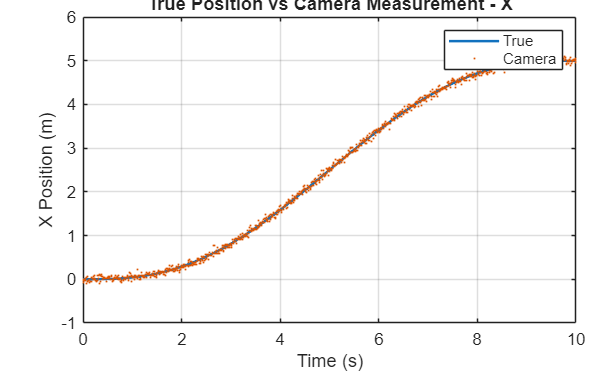


legend( ...
    'True', ...
    'Camera');

grid on;

The three-dimensional plot checks the complete spatial effect of camera position noise. The noisy points should cluster around the true trajectory rather than systematically shift away from it.


$$\mathbf p_{camera}=\mathbf p_{true}+\mathbf n_p$$


figure;

plot3( ...
    p_true(:,1), ...
    p_true(:,2), ...
    p_true(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    p_camera(:,1), ...
    p_camera(:,2), ...
    p_camera(:,3), ...
    '.', ...
    'MarkerSize',3);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('True Trajectory vs Noisy Camera Measurements');

legend( ...
    'True trajectory', ...
    'Camera measurements');

The accelerometer is compared with the specific force that was used to generate it. The calculation removes gravity and expresses the result in body coordinates before plotting it against the noisy measurement.


$$\mathbf f_{true}=R_{true}^T(\mathbf a_{true}-\mathbf g)$$


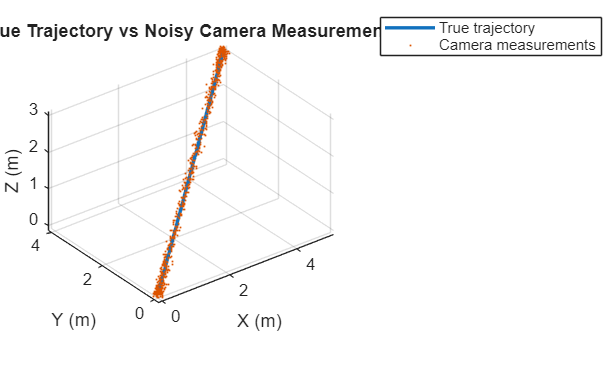

%% 13. Plot True Specific Force vs IMU

% Calculate true body-frame specific force
specific_force_true = zeros(numSamples,3);

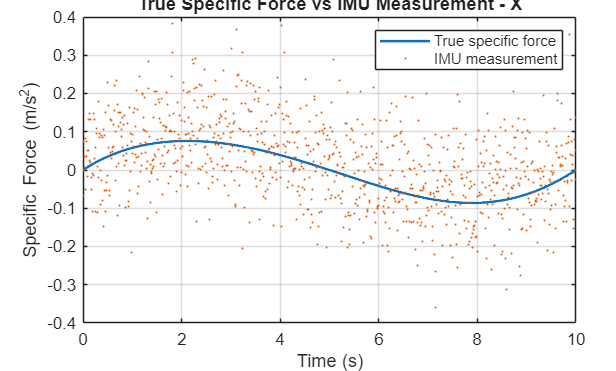


for k = 1:numSamples

    specific_force_true(k,:) = ...
        (R_true(:,:,k)' * ...
        (a_true(k,:)' - g))';

end


figure;

plot( ...
    t, ...
    specific_force_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    a_imu(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('Specific Force (m/s^2)');

title('True Specific Force vs IMU Measurement - X');

legend( ...
    'True specific force', ...
    'IMU measurement');

grid on;

The gyroscope plot compares the ideal angular velocity with the measured value. The same block also computes RMS noise levels after subtracting the known bias, allowing us to check whether the simulated random noise has approximately the intended scale.


$$RMSE=\sqrt{\frac1N\sum_{k=1}^{N}e_k^2}$$


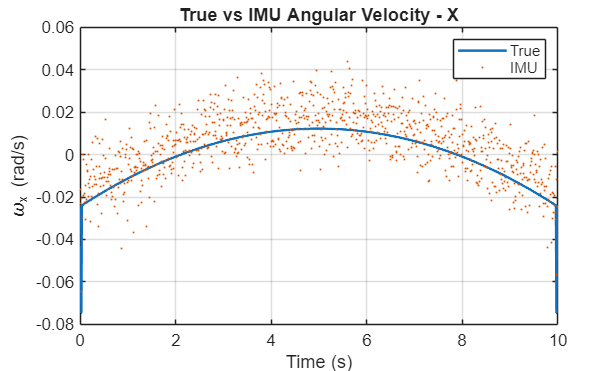

figure;

plot( ...
    t, ...
    omega_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    omega_imu(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('\omega_x (rad/s)');

title('True vs IMU Angular Velocity - X');

legend( ...
    'True', ...
    'IMU');

grid on;



%% 15. Calculate Camera Position Noise RMS

position_error = ...
    p_camera - p_true;

camera_position_rms = ...
    sqrt(mean(position_error(:).^2));


%% 16. Calculate Accelerometer Noise RMS

acceleration_noise_error = ...
    zeros(numSamples,3);

for k = 1:numSamples

    acceleration_noise_error(k,:) = ...
        a_imu(k,:) ...
        - specific_force_true(k,:) ...
        - accel_bias;

end

accelerometer_noise_rms = ...
    sqrt(mean(acceleration_noise_error(:).^2));


%% 17. Calculate Gyroscope Noise RMS

gyro_bias_matrix = ...
    repmat(gyro_bias,numSamples,1);

gyro_noise_error = ...
    omega_imu ...
    - omega_true ...
    - gyro_bias_matrix;

gyroscope_noise_rms = ...
    sqrt(mean(gyro_noise_error(:).^2));


The printed sensor results collect the scalar noise measures into a readable check. These values are diagnostics of the synthetic sensor model; they are not being fed back into the state.

%% 18. Display Sensor Results

fprintf('\n');
fprintf('========================================\n');
fprintf('SYNTHETIC SENSOR RESULTS\n');

fprintf('========================================\n');

SYNTHETIC SENSOR RESULTS


fprintf( ...
    'Camera position noise RMS = %.4f m\n', ...
    camera_position_rms);


Camera position noise RMS = 0.0508 m


fprintf( ...
    'Accelerometer noise RMS = %.4f m/s^2\n', ...
    accelerometer_noise_rms);

fprintf( ...
    'Gyroscope noise RMS = %.4f rad/s\n', ...
    gyroscope_noise_rms);

Accelerometer noise RMS = 0.1019 m/s^2


Gyroscope noise RMS = 0.0101 rad/s


## 10. Save the complete synthetic sensor data

The estimator in Step 4 needs the noisy camera position and attitude together with the IMU measurements. We therefore save the true quantities, sensor measurements and sensor parameters in the same MAT-file. This also allows later files to calculate estimation errors against ground truth without regenerating the experiment.


$$\mathcal{D}=\{\mathbf{p}_{camera},R_{camera},\mathbf{a}_{imu},\mathbf{\omega}_{imu},\mathcal{X}_{true},\text{sensor parameters}\}$$




%% 19. Save Step 3 Results
save( ...
    'drone_toy_model.mat', ...
    'p0', ...
    'pf', ...
    'v0', ...
    'vf', ...
    'a0', ...
    'af', ...
    'T', ...
    't', ...
    'dt', ...
    'pd', ...
    'vd', ...
    'ad', ...
    'p_true', ...
    'v_true', ...
    'a_true', ...
    'R_true', ...
    'omega_true', ...
    'p_camera', ...
    'R_camera', ...
    'a_imu', ...
    'omega_imu', ...
    'sigma_position', ...
    'sigma_camera_angle', ...
    'sigma_acceleration', ...
    'sigma_gyro', ...
    'accel_bias', ...
    'gyro_bias');

fprintf('\nStep 3 results saved to drone_toy_model.mat\n');


Step 3 results saved to drone_toy_model.mat


## 11. Mathematical utility functions

The last block defines two small functions used throughout the sensor model and later stages. The skew function converts a vector v = [v1 v2 v3]^T into the skew-symmetric matrix [v]_x such that [v]_x u = v x u.


$$[\mathbf{v}]_\times=\left[\matrix{0 & -v_3 & v_2 \cr v_3 & 0 & -v_1 \cr -v_2 & v_1 & 0}\right]$$


The logSO3 function performs the inverse operation of the rotation exponential for a rotation matrix R. Its output is the rotation vector whose direction is the rotation axis and whose magnitude is the rotation angle.


$$\theta=\cos^{-1}\left(\frac{\mathrm{tr}(R)-1}{2}\right), \mathrm{Log}(R)=\frac{\theta}{2\sin\theta}\left[\matrix{R_{32}-R_{23} \cr R_{13}-R_{31} \cr R_{21}-R_{12}}\right]$$


The clamp on cos(theta) protects against tiny floating-point values outside the mathematical interval [-1,1]. The small-angle branch avoids division by a quantity that approaches zero.


%% Local Functions

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = logSO3(R)

    cos_theta = ...
        (trace(R)-1)/2;

    cos_theta = ...
        max(-1,min(1,cos_theta));

    theta = ...
        acos(cos_theta);

    if theta < 1e-8

        v = zeros(3,1);

    else

        v = ...
            theta/(2*sin(theta)) * ...
            [
                R(3,2)-R(2,3);
                R(1,3)-R(3,1);
                R(2,1)-R(1,2)
            ];

    end

end
